# # This script is to plot figures

# Experiment 1: BP

load("BP_syn.mat")

for i=1:4
    for j=1:20
        OUT2.time{i,j}=OUT2.cpu{i,j}(end);

ans =    5.911997500000000


        OUT3.time{i,j}=OUT3.cpu{i,j}(end);
        OUT4.time{i,j}=OUT4.cpu{i,j}(end);
    end
end

RGB = cbrewer('qual','Paired',12,'linear');
color = [RGB(6,:);RGB(8,:);RGB(4,:)];
M=[1000 2000 3000 5000];
N=[2000 3000 5000 10000];
for i=1:4
    figure(i);
    h=boxplot([OUT2.time{i,:};OUT3.time{i,:};OUT4.time{i,:}]','Labels',{'aIAL','rIAL1','rIAL2'},'Whisker',2.5);
    set(h,'LineWidth',1.0);
    h = findobj(gca,'Tag','Box');
    for jj=1:length(h)
        patch(get(h(jj),'XData'),get(h(jj),'YData'),color(jj,:),'FaceAlpha',.5);
    end
    ylabel('CPU(s)','FontSize',12);
    title(sprintf('(%d,%d)',M(i),N(i)),'FontSize',12);
end


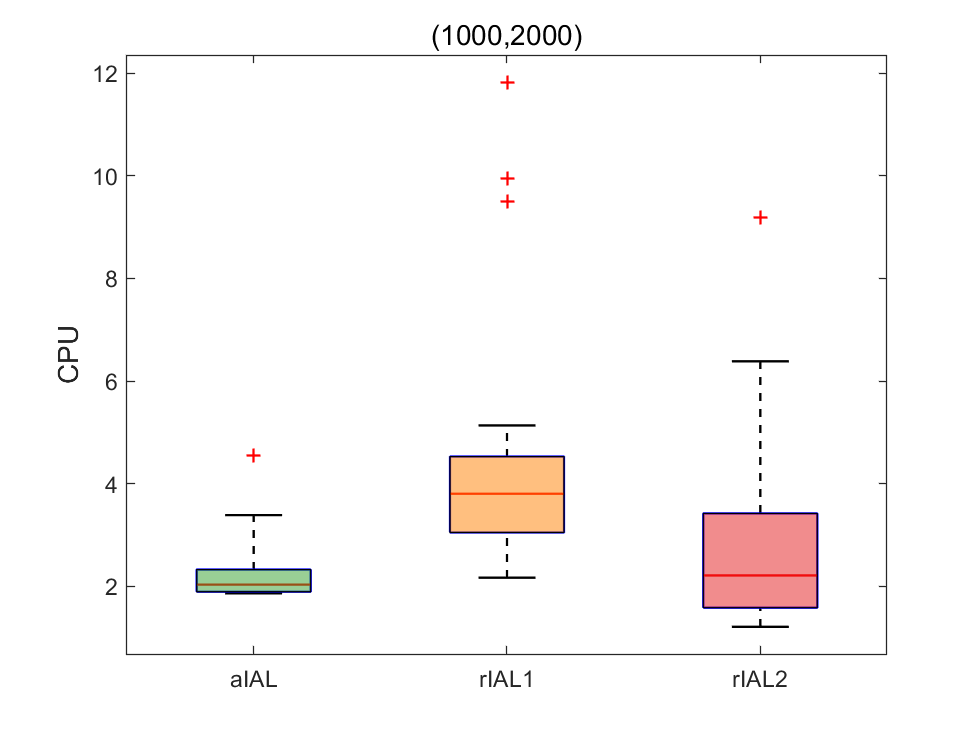

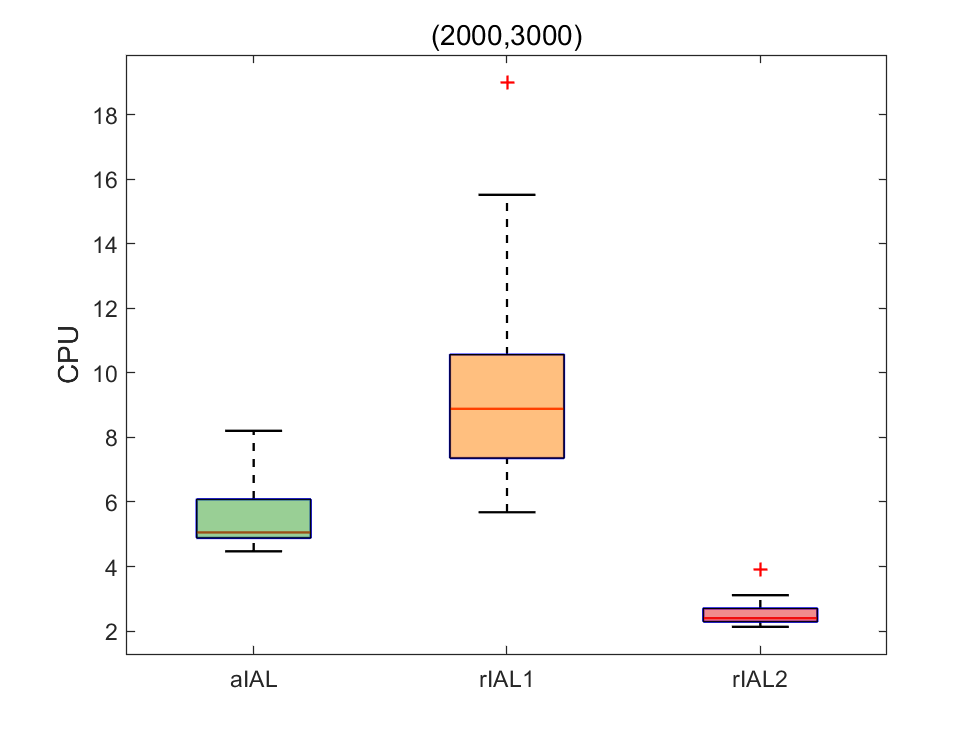

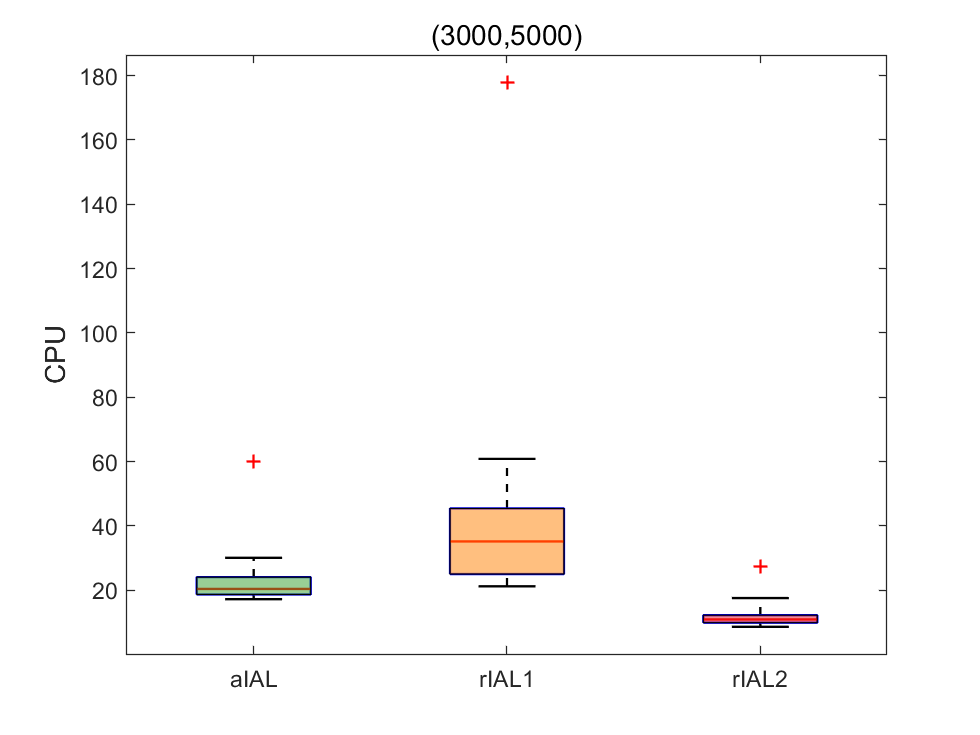

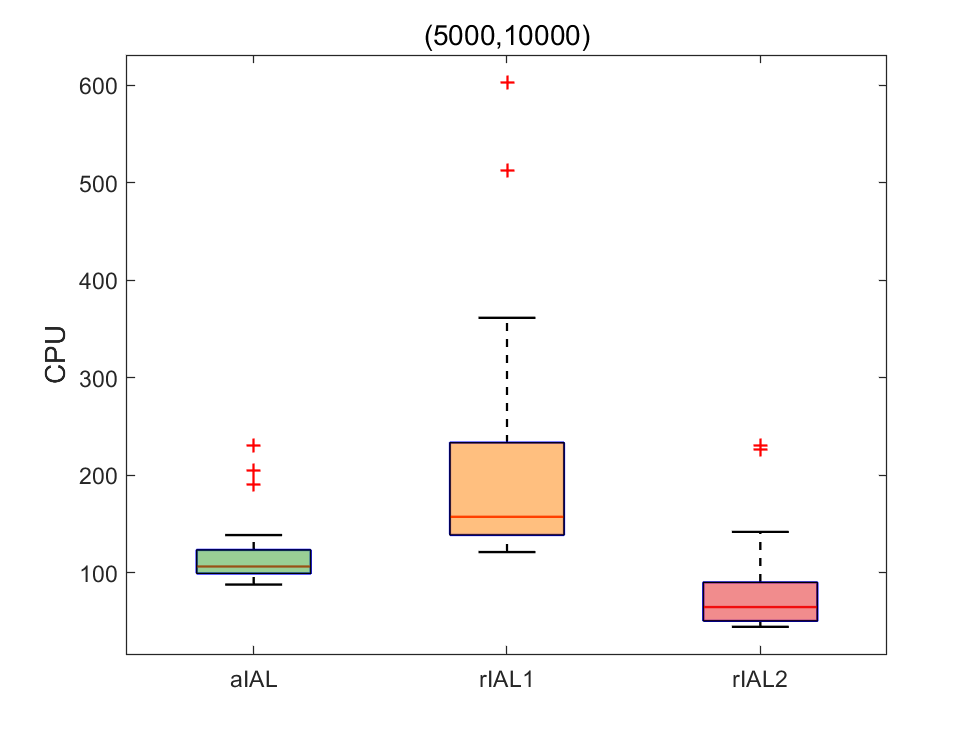

for i=1:4
    for j=1:20
        OUT2.objerr{i,j}=OUT2.obj{i,j}(end);
        OUT3.objerr{i,j}=OUT3.obj{i,j}(end);

        OUT4.objerr{i,j}=OUT4.obj{i,j}(end);

c =      1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0


ans = 'double'

ans = 1×20 cell 数组
    {[0 1.564117700000000 1.988471600000000 2.106514100000000 2.142499200000000 2.183732300000000 2.217336100000000 2.237494700000000 2.262609600000000 2.283789100000000 2.304740500000000 2.318555900000000 2.339027500000000]}    {[0 1.171456100000000 1.527534900000000 1.652656600000000 1.702163400000000 1.733819300000000 1.754640300000000 1.775208200000000 1.784658800000000 1.809633000000000 1.826578200000000 1.856361500000000 1.865013100000000 1.877229300000000]}    {[0 1.472452200000000 1.855333300000000 1.912502800000000 2.073346400000000 2.177070400000000 2.218253400000000 2.228150800000000 2.246506500000000 2.265707100000000 2.287270800000000 2.309128400000001 2.313844900000000]}    {[0 1.219621400000000 1.587198400000000 1.633342400000000 1.676592200000000 1.707258500000000 1.743394800000000 1.757117700000000 1.782344600000000 1.799653500000000 1.816833200000000 1.838151800000000 1.864248400000000 1.869787300000000 1.878199000000000]}    {[0 1.185141400000000 1

ans =    504


ans =     14


        OUT2.relerr{i,j}=OUT2.rel{i,j}(end);
        OUT3.relerr{i,j}=OUT3.rel{i,j}(end);
        OUT4.relerr{i,j}=OUT4.rel{i,j}(end);
    end
end

for i=1:4
    OUT2.mean_time(i)=mean([OUT2.time{i,:}]);
    OUT2.mean_objerr(i)=mean([OUT2.objerr{i,:}]);
    OUT2.mean_relerr(i)=mean([OUT2.relerr{i,:}]);
    OUT2.mean_iter(i)=mean([OUT2.Iter{i,:}]);
    OUT2.mean_k(i)=mean([OUT2.k{i,:}]);
    OUT3.mean_time(i)=mean([OUT3.time{i,:}]);
    OUT3.mean_objerr(i)=mean([OUT3.objerr{i,:}]);
    OUT3.mean_relerr(i)=mean([OUT3.relerr{i,:}]);
    OUT3.mean_iter(i)=mean([OUT3.Iter{i,:}]);
    OUT3.mean_k(i)=mean([OUT3.k{i,:}]);
    OUT4.mean_time(i)=mean([OUT4.time{i,:}]);
    OUT4.mean_objerr(i)=mean([OUT4.objerr{i,:}]);
    OUT4.mean_relerr(i)=mean([OUT4.relerr{i,:}]);
    OUT4.mean_iter(i)=mean([OUT4.Iter{i,:}]);
    OUT4.mean_k(i)=mean([OUT4.k{i,:}]);
end


for i = 1:4
    fprintf('& &%.1e & %.1e & %.1e & & %.1e & %.1e & %.1e & & %.1f & %.1f &\\textbf{%.1f} & & %.1f(%.1f)& %.1f(%.1f)& %.1f(%.1f)\n', ...
    OUT2.mean_objerr(i),OUT3.mean_objerr(i),OUT4.mean_objerr(i),OUT2.mean_relerr(i),OUT3.mean_relerr(i),OUT4.mean_relerr(i),OUT2.mean_time(i),OUT3.mean_time(i),OUT4.mean_time(i), ...
    OUT2.mean_k(i),OUT2.mean_iter(i),OUT3.mean_k(i),OUT3.mean_iter(i),OUT4.mean_k(i),OUT4.mean_iter(i));
end

`2.5e-06 & 2.9e-06 1.2e-02 & & 5.0e-08 & 4.9e-08 1.6e-04 & & 2.3 & 4.6 &\textbf{3.0} & & 17.9(536.0)& 19.6(1089.1)& 129.2(578.6)`

`3.0e-06 & 1.9e-06 2.4e-06 & & 3.6e-08 & 3.3e-08 3.3e-08 & & 5.5 & 9.5 &\textbf{2.5} & & 14.4(403.6)& 17.0(696.9)& 47.1(174.5)`

`2.0e-06 & 6.1e-06 6.0e-06 & & 2.9e-08 & 1.0e-07 9.7e-08 & & 23.2 & 42.9 &\textbf{12.1} & & 25.7(537.9)& 31.4(983.6)& 62.9(248.3)`

`4.7e-06 & 5.1e-06 2.8e-06 & & 2.2e-08 & 2.2e-08 2.2e-08 & & 122.5 & 217.2 &\textbf{84.5} & & 15.4(843.7)& 27.0(1480.2)& 124.2(501.9)`

M=[1000 2000 3000 5000];
N=[2000 3000 5000 10000];
RGB = cbrewer('qual','Paired',12,'linear');
for j=1:4
    for i=1:5
%         if j==1
%             figure(3*j+i)

& &2.5e-06 & 2.9e-06 & 1.2e-02 & & 5.0e-08 & 4.9e-08 & 1.6e-04 & & 2.3 & 4.6 &\textbf{3.0} & & 17.9(536.0)& 19.6(1089.1)& 129.2(578.6)
& &3.0e-06 & 1.9e-06 & 2.4e-06 & & 3.6e-08 & 3.3e-08 & 3.3e-08 & & 5.5 & 9.5 &\textbf{2.5} & & 14.4(403.6)& 17.0(696.9)& 47.1(174.5)
& &2.0e-06 & 6.1e-06 & 6.0e-06 & & 2.9e-08 & 1.0e-07 & 9.7e-08 & & 23.2 & 42.9 &\textbf{12.1} & & 25.7(537.9)& 31.4(983.6)& 62.9(248.3)
& &4.7e-06 & 5.1e-06 & 2.8e-06 & & 2.2e-08 & 2.2e-08 & 2.2e-08 & & 122.5 & 217.2 &\textbf{84.5} & & 15.4(843.7)& 27.0(1480.2)& 124.2(501.9)


%             semilogy(OUT2(j,i).CPU(1:2:end),OUT2(j,i).Axb2(1:2:end),'o-','Color',RGB(4,:),'LineWidth',1.5);hold on;
%             semilogy(OUT3(j,i).CPU,OUT3(j,i).Axb2,'*-','Color',RGB(8,:),'LineWidth',1.5);hold on;
%             semilogy(OUT4(j,i).CPU,OUT4(j,i).Axb2,'s-','Color',RGB(6,:),'LineWidth',1.5);hold off;
%             legend('aIAL','rIAL1','rIAL2');
%             xlabel('CPU time (s)');
%             title(sprintf("(%d,%d)",M(j),N(j)));
%             ylabel('$\|Bx-d\|/(1+\|d\|)$','interpreter','latex');
%         else
            figure(4*j+i)
            semilogy(OUT2.cpu{j,i},OUT2.resi{j,i},'o-','Color',RGB(4,:),'LineWidth',1.5);hold on;
            semilogy(OUT3.cpu{j,i},OUT3.resi{j,i},'*-','Color',RGB(8,:),'LineWidth',1.5);hold on;
            semilogy(OUT4.cpu{j,i},OUT4.resi{j,i},'s-','Color',RGB(6,:),'LineWidth',1.5);hold off;
            legend('aIAL','rIAL1','rIAL2');
            xlabel('CPU time (s)');
            title(sprintf("(%d,%d)",M(j),N(j)));
            ylabel('$\|Ax^k-b\|^2$','interpreter','latex');
%         end
    end
end

# Experiment 2: Synthetic data

load("out_syn.mat")

dim=[200]
for j = 1:4
    
    for i = 1:3
        fprintf('%.2e & %.1e & %.1e &%.1e & & %.1f & %.1f &\\textbf{%.1f} & & %d(%d)& %d(%d)& %d(%d)\n', ...
    OUT1(j,i).obj,OUT2(j,i).objerr,OUT3(j,i).objerr,OUT4(j,i).objerr,OUT2(j,i).cpu,OUT3(j,i).cpu,OUT4(j,i).cpu, ...
    OUT2(j,i).k,OUT2(j,i).iter,OUT3(j,i).k,OUT3(j,i).iter,OUT4(j,i).k,OUT4(j,i).iter);
    end
end



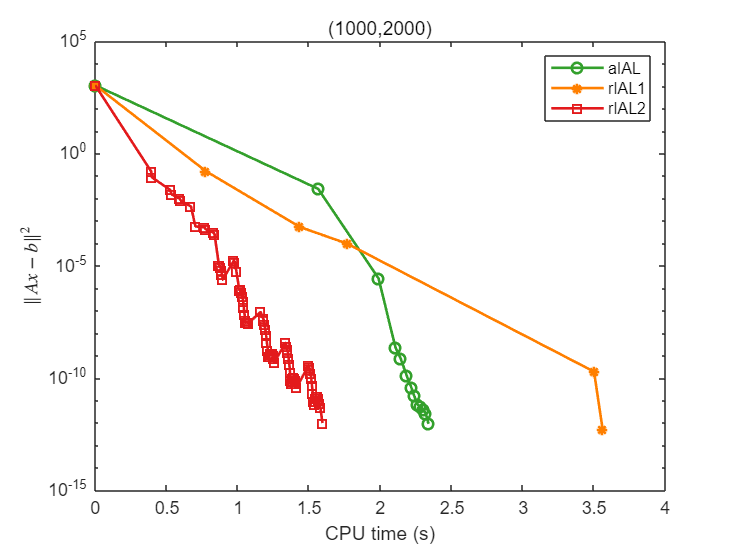

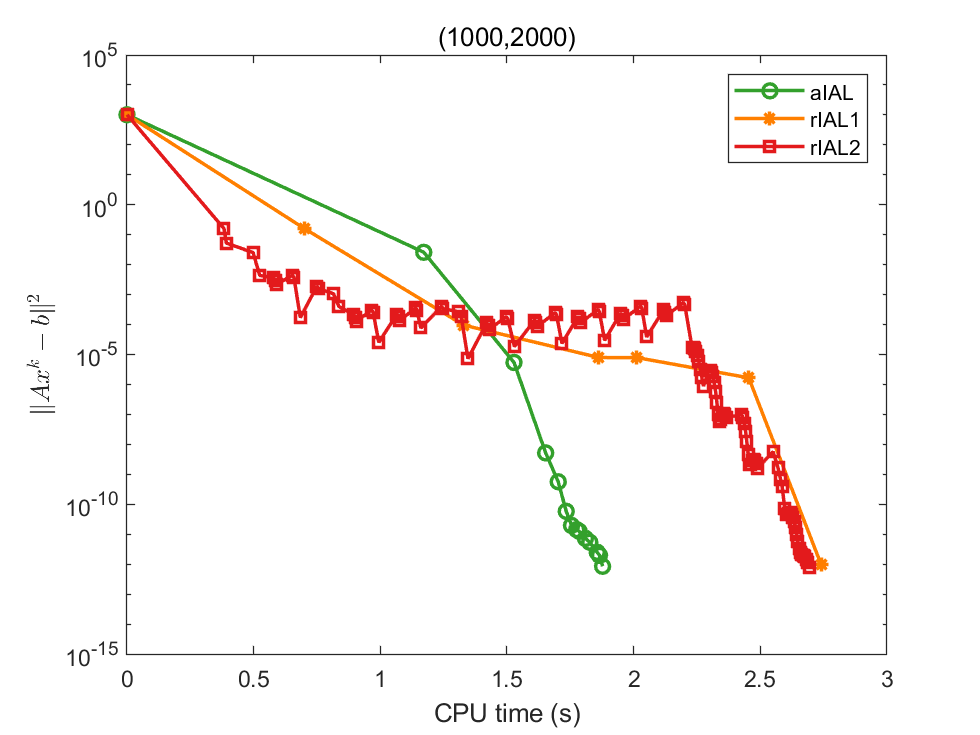

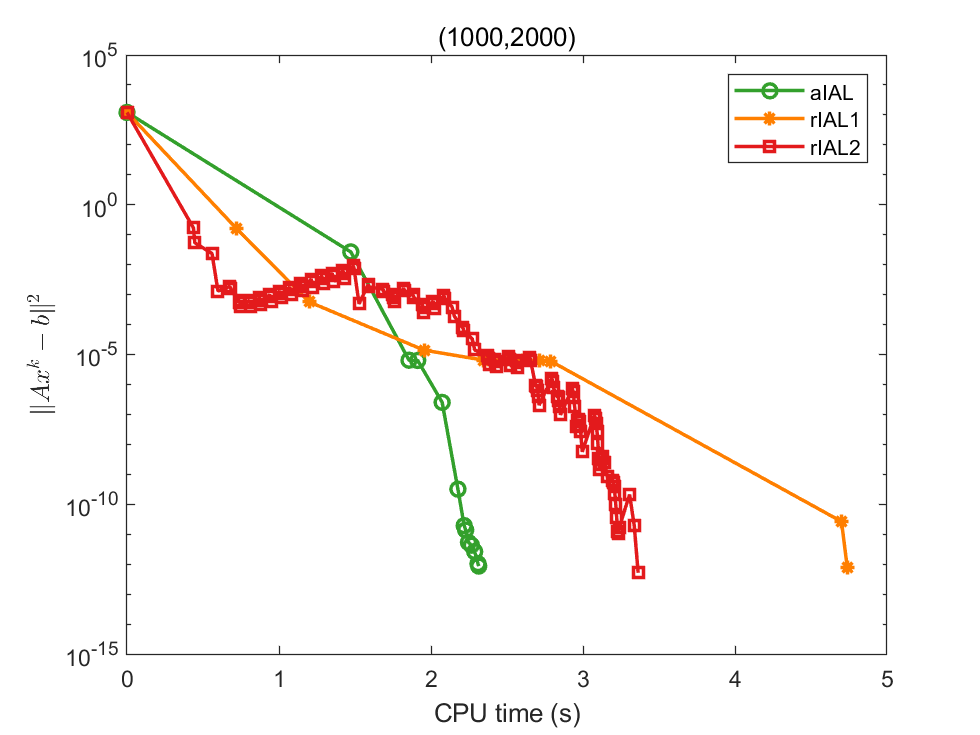

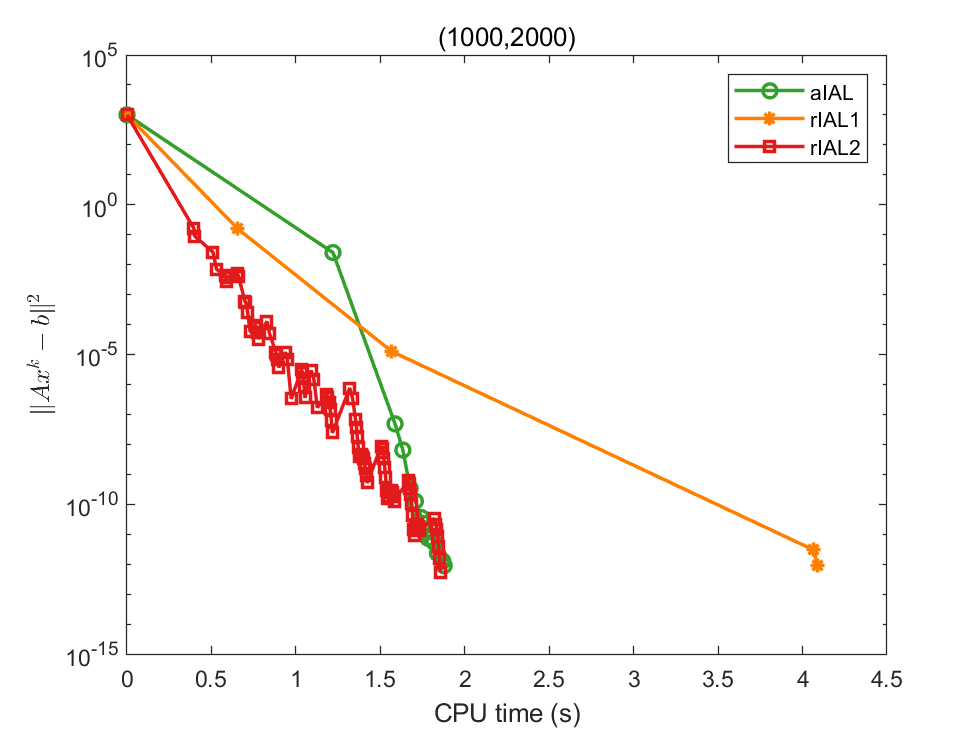

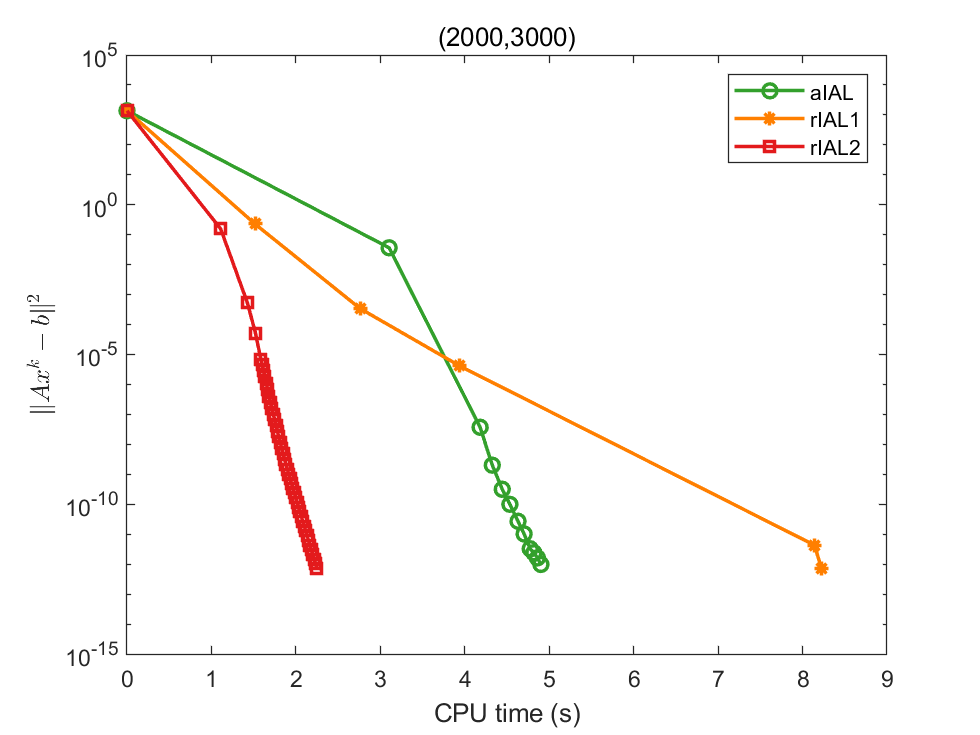

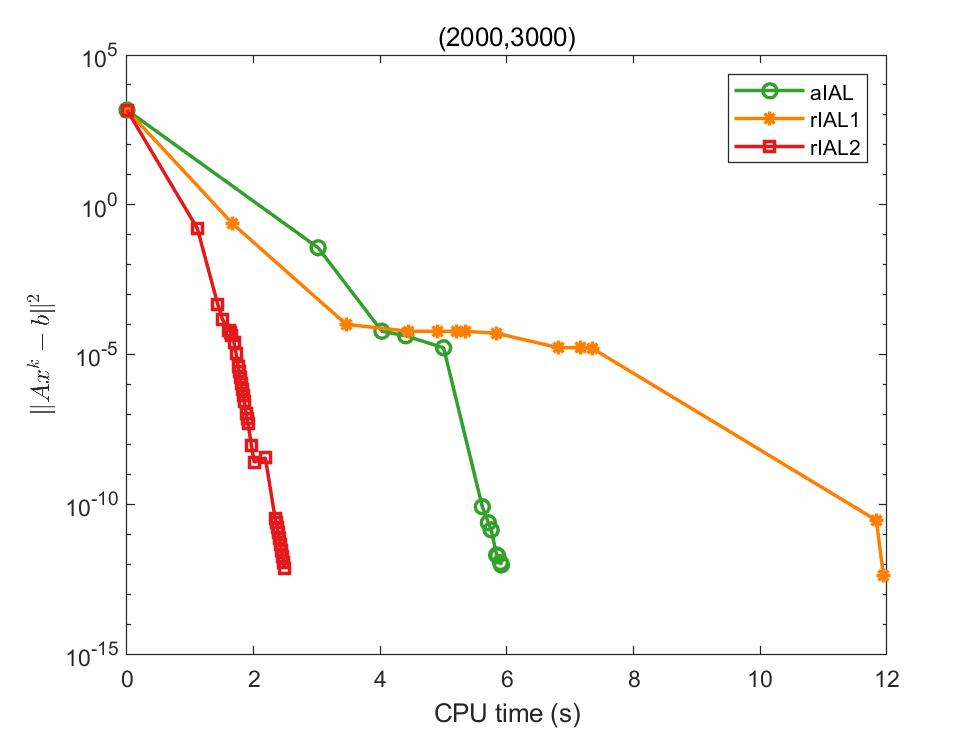

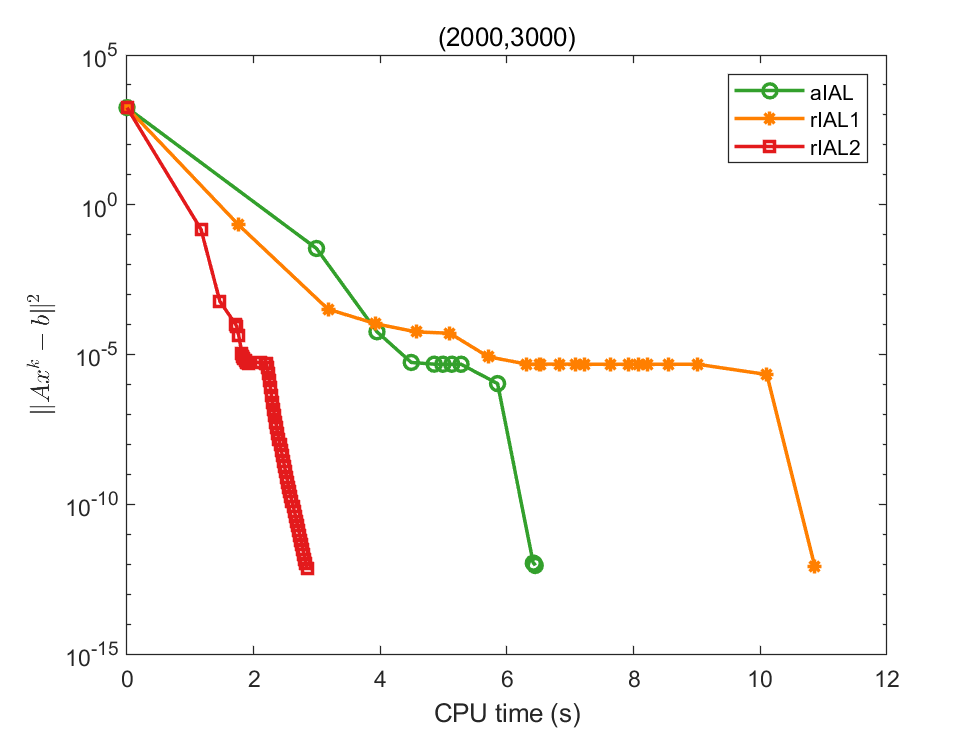

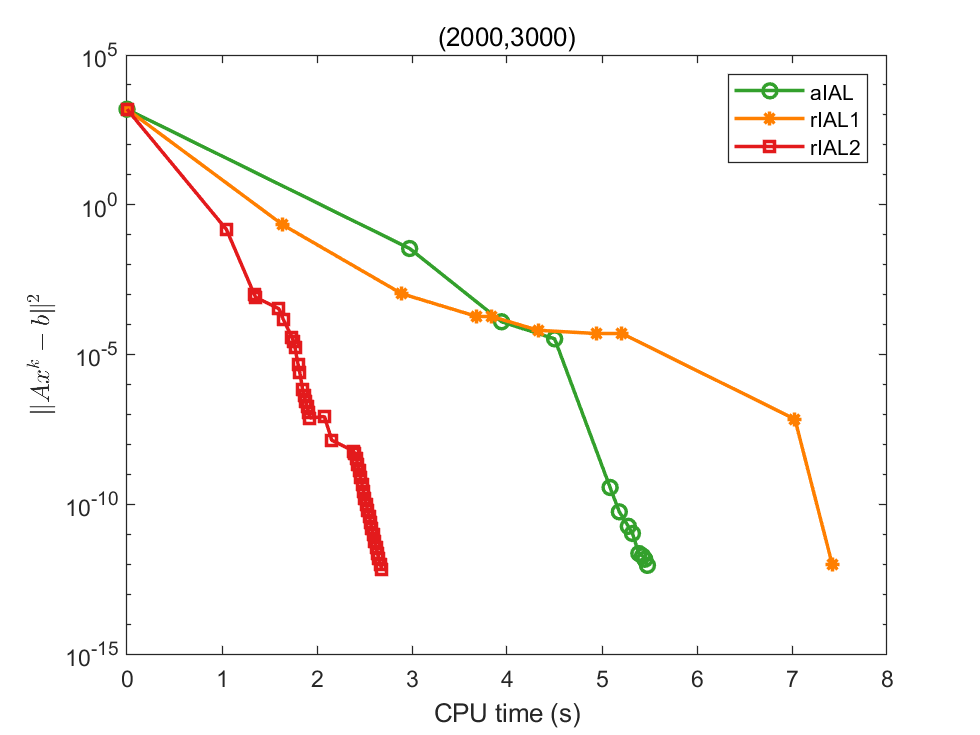

M=[1000 3000 5000 8000];

N=[3000 5000 8000 10000];
RGB = cbrewer('qual','Paired',12,'linear');
for j=1:4
    for i=2:2

错误使用 load
找不到文件或目录 'out_syn.mat'。

        if j==1
            figure(3*j+i)

dim =    200


            semilogy(OUT2(j,i).CPU(1:2:end),OUT2(j,i).Axb2(1:2:end),'o-','Color',RGB(4,:),'LineWidth',1.5);hold on;
            semilogy(OUT3(j,i).CPU,OUT3(j,i).Axb2,'*-','Color',RGB(8,:),'LineWidth',1.5);hold on;
            semilogy(OUT4(j,i).CPU,OUT4(j,i).Axb2,'s-','Color',RGB(6,:),'LineWidth',1.5);hold off;
            legend('aIAL','rIAL1','rIAL2');
            xlabel('CPU time (s)');
            title(sprintf("(%d,%d)",M(j),N(j)));
            ylabel('$\|Bx-d\|/(1+\|d\|)$','interpreter','latex');
        else

4.62e+04 & -5.5e-03 & -6.0e-03 &-2.2e-03 & & 193.1 & 25.2 &\textbf{9.3} & & 65(17835)& 18(2342)& 34(778)
4.68e+03 & -4.8e-04 & -5.7e-04 &-2.2e-04 & & 134.5 & 24.5 &\textbf{13.6} & & 42(12629)& 12(2302)& 29(1146)
4.69e+02 & -8.7e-05 & -9.8e-05 &-5.6e-06 & & 109.7 & 40.3 &\textbf{35.0} & & 24(10181)& 8(3699)& 26(2940)
1.77e+05 & -1.5e-02 & -1.5e-02 &-8.9e-03 & & 2648.6 & 189.3 &\textbf{46.5} & & 161(47220)& 37(3330)& 49(782)
1.78e+04 & -1.7e-03 & -1.9e-03 &-7.8e-04 & & 1121.2 & 107.5 &\textbf{53.4} & & 88(20104)& 21(1915)& 36(899)
1.79e+03 & -2.7e-04 & -3.2e-04 &-1.4e-04 & & 709.3 & 144.6 &\textbf{112.1} & & 52(12706)& 13(2541)& 36(1834)
6.17e+05 & -5.0e-02 & -5.3e-02 &-1.1e-02 & & 6945.4 & 516.1 &\textbf{113.2} & & 148(43734)& 34(2980)& 46(621)
6.23e+04 & -6.8e-03 & -7.1e-03 &-2.2e-03 & & 4501.0 & 352.1 &\textbf{165.6} & & 105(29036)& 25(2207)& 39(983)
6.23e+03 & -9.0e-04 & -9.8e-04 &-4.1e-04 & & 2918.3 & 427.7 &\textbf{332.0} & & 57(17357)& 15(2462)& 39(1802)
9.98e+05 & -1.9e+00 & -6.9

            figure(3*j+i)
            semilogy(OUT2(j,i).CPU(1:3:end),OUT2(j,i).Axb2(1:3:end),'o-','Color',RGB(4,:),'LineWidth',1.5);hold on;
            semilogy(OUT3(j,i).CPU(1:2:end),OUT3(j,i).Axb2(1:2:end),'*-','Color',RGB(8,:),'LineWidth',1.5);hold on;
            semilogy(OUT4(j,i).CPU(1:2:end),OUT4(j,i).Axb2(1:2:end),'s-','Color',RGB(6,:),'LineWidth',1.5);hold off;
            legend('aIAL','rIAL1','rIAL2');
            xlabel('CPU time (s)');
            title(sprintf("(%d,%d)",M(j),N(j)));
            ylabel('$\|Bx-d\|/(1+\|d\|)$','interpreter','latex');
        end
    end
end

# Experiment 2: Real data

load('out_real1.mat')


for i = 2:2
    fprintf('%.2e & %.1e %.1e & & %.1f &\\textbf{%.1f} & & %d(%d)& %d(%d)\n', ...
    OUT1(1,i).obj,OUT3(1,i).objerr,OUT4(1,i).objerr,OUT3(1,i).cpu,OUT4(1,i).cpu, ...
    OUT3(1,i).k,OUT3(1,i).iter,OUT4(1,i).k,OUT4(1,i).iter);
end

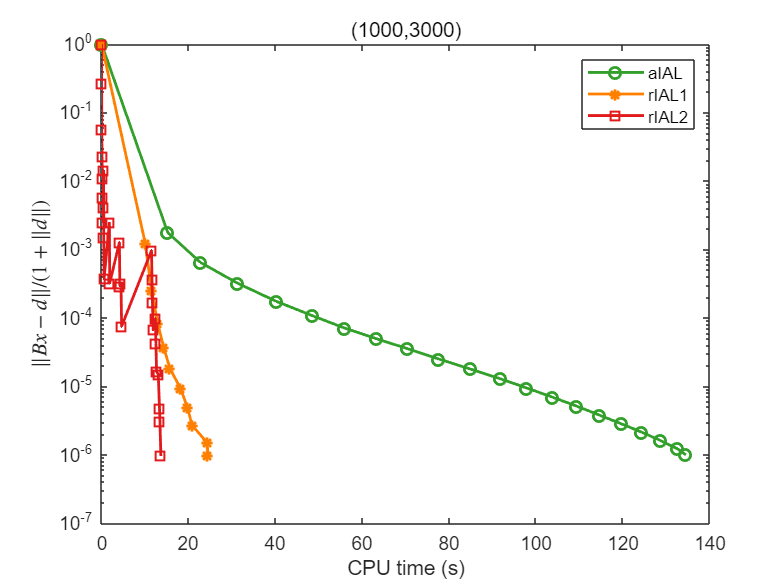

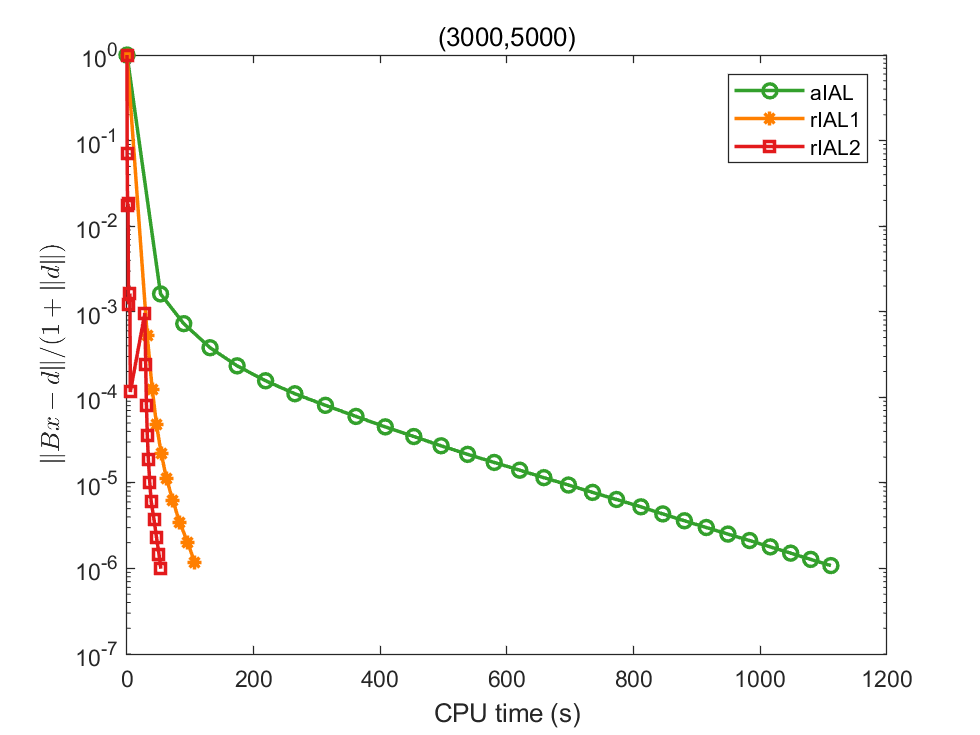

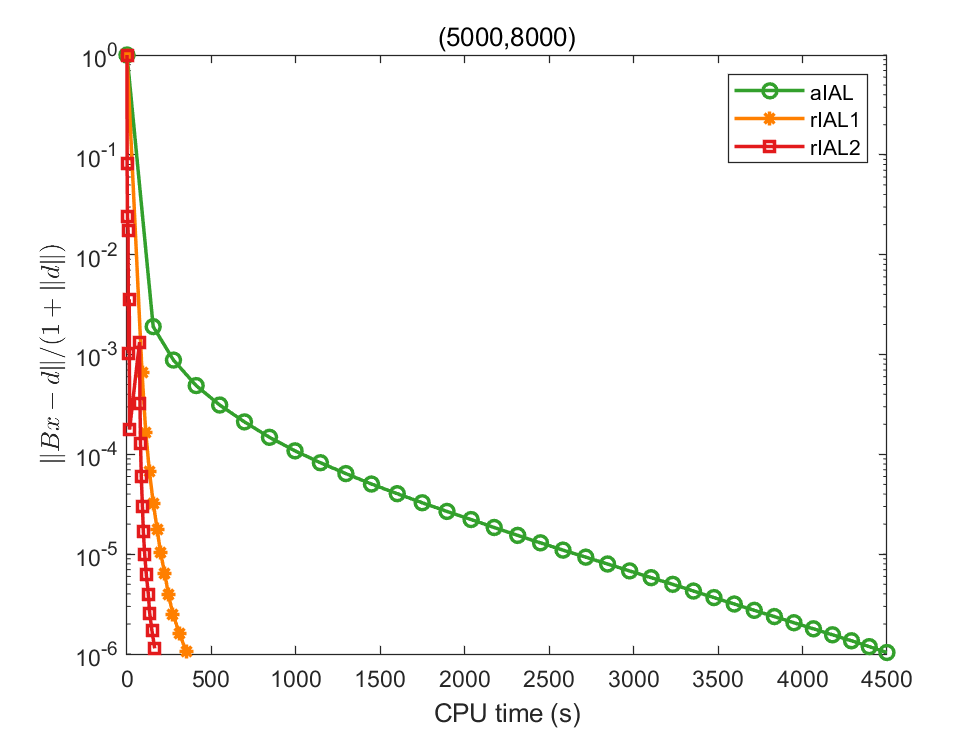

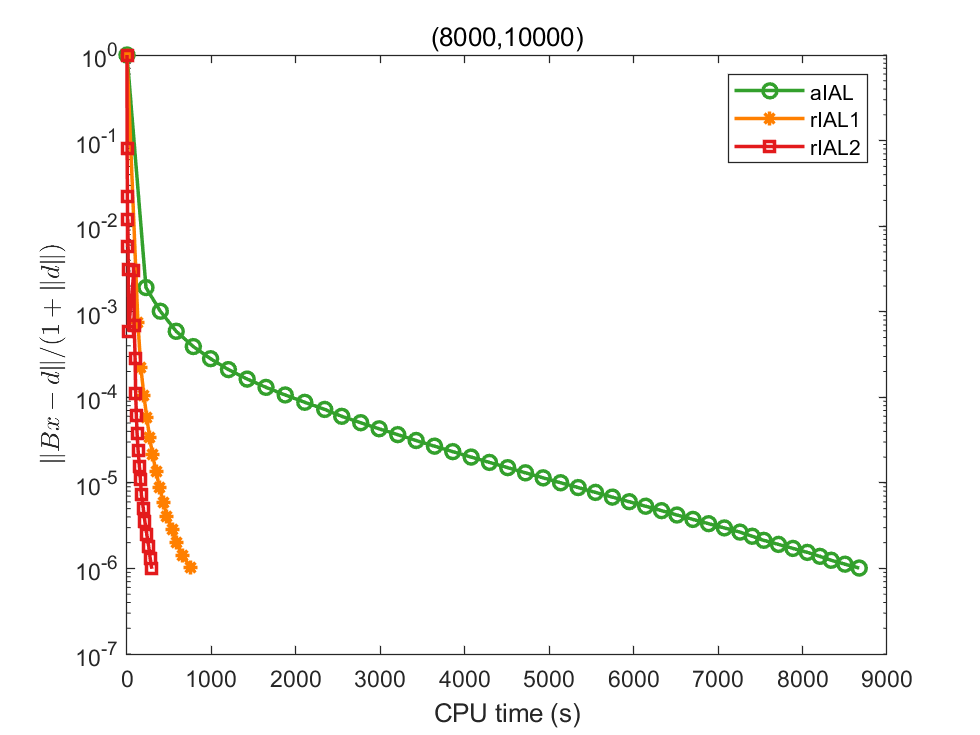

load('out_real.mat')
for j = 2:5
    for i = 1:2
        fprintf('%.2e & %.1e %.1e & & %.1f &\\textbf{%.1f} & & %d(%d)& %d(%d)\n', ...
    OUT1(j,i).obj,OUT3(j,i).objerr,OUT4(j,i).objerr,OUT3(j,i).cpu,OUT4(j,i).cpu, ...
    OUT3(j,i).k,OUT3(j,i).iter,OUT4(j,i).k,OUT4(j,i).iter);
    end
end




RGB = cbrewer('qual','Paired',12,'linear');
semilogy(OUT3(4,1).CPU,OUT3(4,1).Axb2,'*-','Color',RGB(8,:),'LineWidth',1.5);hold on;
semilogy(OUT4(4,1).CPU,OUT4(4,1).Axb2,'s-','Color',RGB(6,:),'LineWidth',1.5);hold off;
legend('rIAL1','rIAL2');
xlabel('CPU time (s)');
title('\textbf{mpg7}','interpreter','latex');
ylabel('$\|Bx-d\|/(1+\|d\|)$','interpreter','latex');

RGB = cbrewer('qual','Paired',12,'linear');
semilogy(OUT3(5,1).CPU,OUT3(5,1).Axb2,'*-','Color',RGB(8,:),'LineWidth',1.5);hold on;
semilogy(OUT4(5,1).CPU,OUT4(5,1).Axb2,'s-','Color',RGB(6,:),'LineWidth',1.5);hold off;
legend('rIAL1','rIAL2');
xlabel('CPU time (s)');
title('\textbf{space\_ga9}','interpreter','latex');
ylabel('$\|Bx-d\|/(1+\|d\|)$','interpreter','latex');